# this code is to compare only Poisson and only Gaussian in the CW case.

clc
clear

addpath(genpath('F:\OneDrive\UK_projects_local\project in UK 2024\MCX\mcx_git'))

## 2D CSF simulation setup

clear cfg_csf;

% % % % ------------general setting---------
cfg_csf.nphoton = 1e9;
cfg_csf.gpuid = '11'; % use two GPUs
cfg_csf.workload = [10,10];  % evenly use the two GPUs
cfg_csf.autopilot = 1;
cfg_csf.maxdetphoton = 1e7; % enough
brain_radius = 70;
cfg_csf.vol = permute(uint8(zeros([2*brain_radius,2*brain_radius])), [3, 1, 2]); % from 2d to 3d
cfg_csf.tstart = 0;
cfg_csf.tend = 3e-9;
cfg_csf.tstep = 5e-11;
cfg_csf.debuglevel = 'P'; % show progress bar
cfg_csf.unitinmm = 1;
cfg_csf.issrcfrom0 = 1;  % 1-first voxel is [0 0 0], [0]- first voxel is [1 1 1]
BinFlag = ((1:length(cfg_csf.tstart:cfg_csf.tstep:cfg_csf.tend)-1)'-1).*cfg_csf.tstep+cfg_csf.tstep/2; % the bin value of each timebin
source_angle = linspace(-pi/3,0,9)'; % angle range of source angle
det_angle = linspace(-pi/3,pi/3,17)'; % angle range of det angle
% source_angle = linspace(-pi/3,0,5)'; % angle range of source angle
% det_angle = linspace(-pi/3,pi/3,9)'; % angle range of det angle
SD_dist = abs(source_angle'-det_angle).*brain_radius; % get the distance between source and detector in mm
SD_dist = SD_dist(:);
% simu_photon_numbers = round(10.^(7+(11-7)./max(SD_dist).*SD_dist));
% % % % -----------general setting end------------

% -------------build indices for the voxels, use voxel center
center_pos = [brain_radius brain_radius];
[grid_z,grid_y] = ndgrid(linspace(2*brain_radius-0.5,0.5,2*brain_radius),linspace(0.5,2*brain_radius-0.5,2*brain_radius));

dmua_tumour = 0.02; % difference in mua because of tumour

% ------------ set brain segmentation
%----------type [0 air, 1 GM, 2 CSF]
cfg_csf.prop = [0 0 1 1;
    0.033 1 0 1.33;
    0.0420 0.01 0 1.33
    0.033+dmua_tumour 1 0 1.33];

D_from_center = sqrt((grid_z-center_pos(1)).^2+(grid_y-center_pos(2)).^2);
csf_radius = [49 49+3];

for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        switch true
            case D_from_center(i,j)>=csf_radius(1)&&D_from_center(i,j)<csf_radius(2)
                cfg_csf.vol(1, i, j) = 1;
            case D_from_center(i,j)<=brain_radius
                cfg_csf.vol(1, i, j) = 1;
        end
    end
end

% -----------source set---------------------------------------
source_radius = brain_radius; source_angle_rad =  pi/3;
src_pos = [source_radius*cos(source_angle_rad),source_radius*sin(source_angle_rad)];
meas_radius = brain_radius; meas_angle_rad =  - pi/3; % pi/2 -0.5 pi/2+0.01
mea_pos = [meas_radius*cos(meas_angle_rad),meas_radius*sin(meas_angle_rad)];
cfg_csf.srcpos = [0, center_pos(1)+src_pos(1), center_pos(2)+src_pos(2)];
cfg_csf.srcdir = [0 -cos(source_angle_rad) -sin(source_angle_rad)];    % src dir must align in the plan (y-z in this case)
cfg_csf.srctype = 'pencil';
% ---------source set end-----------------------------------

% -------- det set------------
cfg_csf.detpos = [0, center_pos(1)+mea_pos(1), center_pos(2)+mea_pos(2), 2];
% ------- det set end------------


vol_background = cfg_csf.vol; % keep the background of the vol;

tumour_position = 40;

% % % % ----------set tumour-------------------
tuc_pos = [tumour_position 0];
tuC = [center_pos(1)-tuc_pos(1) center_pos(2)+tuc_pos(2)];
tuR = 15;
D2C = sqrt((grid_z-tuC(1)).^2+(grid_y-tuC(2)).^2);
for i = 1:size(cfg_csf.vol,2)
    for j = 1:size(cfg_csf.vol,3)
        if D2C(i,j)<=tuR
            cfg_csf.vol(1, i, j) = 3;
        end
    end
end
% % % % ----------set tumour end-------------------

%--------- set tumour mask-----------
tumour_mask = squeeze(cfg_csf.vol);
tumour_mask(find(tumour_mask~=3))=0;
tumour_mask(find(tumour_mask==3))=1;
tumour_mask = rot90(tumour_mask); % so the tumour_mask here is already rotted
%figure;imagesc(tumour_mask)


% ----------show the setup----------
figure,mcxpreview(cfg_csf); title('setup',FontSize=14); view([90,0]);

函数或变量 'mcxpreview' 无法识别。

% figure,imagesc(double(squeeze(cfg_csf.vol)))
ylabel('X/mm',FontSize=14)
zlabel('Y/mm',FontSize=14)
% ----------show the setup----------


## #data analyse

get rid of one variable by selecting the optimal S-D configuration for each moments and each tumour position

plot the best Fisher Information value and the corresponding S-D distance

also need to consider the time gates

% input tpsf and Jacobians should be the normalized tpsf
close all

%-----------data normalization------------
h = 6.626e-34; % Planck constant in Js
lambda = 800e-9; % wavelength in m
c = 299792453;
sp_eng = h.*c/(lambda); % single photon energy
mpe = 3e-3; % w/mm^2
rep_rate = 300e6; % repetetion rate Hz 300M
single_pulse_energy = mpe./rep_rate; % J/mm^2
single_pulse_photon_count = single_pulse_energy./sp_eng;
exposure_time_tr = 0.1; % unit in second, the exposure time for the TCSPC
bandwidth = 1/exposure_time_tr/2;
DCR = 100; % dark count rate 100/s
TCPSC_lim = 0.01*300e6; % count rate limit for TCSPC
NEP = 1e-13; % W/sqrt(Hz)
Gaussian_var = (NEP*sqrt(bandwidth)/sp_eng).^2;
% sensitive area is set to be 1mm^2
%-----------data normalization------------

% tumour_pos_range = [20:5:40 41 45:5:54 54];
tumour_pos_range = [20:5:40 45:5:54 54];

n = numel(tumour_pos_range);
metrics = {'CW_Gaussian_only','CW_Poisson_only','CW_Gaussian_and_Poisson'};

opt_FI = struct(); opt_D = struct();
for k = 1:numel(metrics)
    opt_FI.(metrics{k}) = zeros(n,1);
    opt_D.(metrics{k})  = zeros(n,1);
end

FI = struct(); D = struct();
for k = 1:numel(metrics)
    FI.(metrics{k}) = zeros(numel(SD_dist),1);
end

depth_index = 1;

% tumour_pos = 10; % debug

% % ------------figures for ploting--------------
% for k = 1:numel(metrics)
%     f(k) = figure('Name',metrics{k}, 'NumberTitle','off');
% end
% % ------------figures for ploting--------------

% tumour_pos = 35;  % debug
for tumour_pos = tumour_pos_range
% for tumour_pos = 25 % debug
    % ----------update tumour mask -------------------
    tuct_pos1 = [tumour_pos 0];
    tuCt = [center_pos(1)-tuct_pos1(1) center_pos(2)+tuct_pos1(2)];
    tuR1 = 15;
    D2Cu = sqrt((grid_z-tuCt(1)).^2+(grid_y-tuCt(2)).^2);
    tumour_mask_it = zeros(2*brain_radius,2*brain_radius);
    for i = 1:size(tumour_mask_it,1)
        for j = 1:size(tumour_mask_it,2)
            if D2Cu(i,j)<=tuR1
                tumour_mask_it(i, j) = 1;
            end
        end
    end
    tumour_mask_it = rot90(tumour_mask_it);
    % figure;imagesc(tumour_mask_it);
    % imagesc(squeeze(log10(abs(sum(jacobians(:,:,:,1),3)))))
    %  ----------update tumour mask -------------------

    data_load = load(sprintf("data5/tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));
    % data_load = load(sprintf("tpsfs_jacobians_dense_AngRang_pi_3_tumpos%d.mat",tumour_pos));

    %------------normalize same input power for all-----
    data_load.tpsfs = data_load.tpsfs.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    data_load.jacobians =  data_load.jacobians.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    % tpsf_normalized = data_load.tpsfs./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;
    % Jacobians_norm = data_load.jacobians./cfg_csf.nphoton.*single_pulse_photon_count.*rep_rate*exposure_time_tr;

    % figure 
    % imagesc(log(abs(squeeze(sum(data_load.jacobians(:,:,:,129),3)))))
    % axis square
    % 
    % figure
    % imagesc(log(abs(squeeze(sum(data_load.jacobians(:,:,:,146),3)))))
    % axis square

    % sd_ind = 129; % debug
    % sd_ind = 146; % debug
    for sd_ind = 52:size(data_load.tpsfs,2) % starting from 52 to get rid of sampling noise
        tpsf_sd =  data_load.tpsfs(:,sd_ind);
        Jacobian_sd = squeeze(data_load.jacobians(:,:,:,sd_ind));
        tpsf_normalized = tpsf_sd;
        Jacobians_norm = Jacobian_sd;
        J_Ni_mua = squeeze(sum(double(tumour_mask_it).*(Jacobians_norm),[1 2]));

        %---------calculate the FI for all situations-----------
        J_m0_Ni = ones(size(tpsf_normalized));
        FI.(metrics{1})(sd_ind) = 1/Gaussian_var.*(J_m0_Ni'*J_Ni_mua).^2; % only Gaussion noise in CW
        FI.(metrics{2})(sd_ind) = 1/sum(tpsf_normalized).*(J_m0_Ni'*J_Ni_mua).^2; % only Poisson noise in CW
        FI.(metrics{3})(sd_ind) = 1/(sum(tpsf_normalized) + Gaussian_var).*(J_m0_Ni'*J_Ni_mua).^2; % combine Gaussian and Poisson noise in CW

        % % --------------debug------------
        % if sd_ind ==129||sd_ind == 146
        %     plot(tpsf_normalized, LineWidth=1)
        %     hold on
        %     grid on
        % 
        %     Fi_all = 1/(sum(tpsf_normalized) + Gaussian_var).*(J_m0_Ni'*J_Ni_mua).^2
        %     jj = (J_m0_Ni'*J_Ni_mua).^2
        %     pc_all = sum(tpsf_normalized)
        % end

    end


    %----------------- get rid of inf----------------
    for ii = 1:numel(metrics)
        FI.(metrics{ii})(isinf(FI.(metrics{ii}))) = 0;
    end

    %-----------------selete optimal value and distance-------------
    for ii = 1:numel(metrics)
        [v,i] = max(FI.(metrics{ii}));
        opt_FI.(metrics{ii})(depth_index) = v;
        opt_D.(metrics{ii})(depth_index) = SD_dist(i);
        % if sum(tumour_pos==[20 35 50])&& ii == 1
        %     v
        %     i
        % end
    end

    depth_index = depth_index + 1;

    %-------------debug---------------
    % plot(log10(FI.CW_Gaussian_and_Poisson),LineWidth=1), hold on
    % grid on
    % problems with 129 and 146
end

## plot the result figure of the optimize Fisher Value

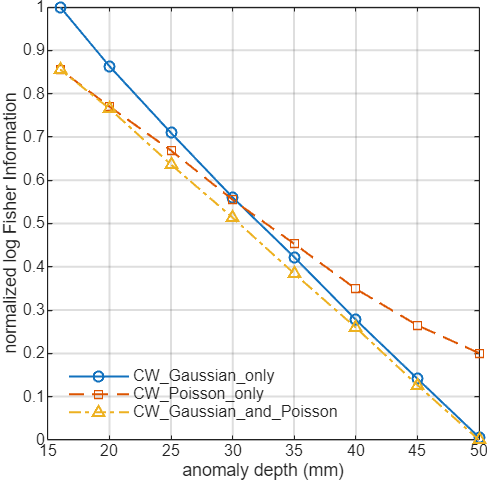

close all;

% -----------Desired sizes (cm)
figW = 17.2/2;   % figure width
% figH = 17.2*0.618;    % figure height, too high for this figure
figH = 17.2/2;    % figure height
axW  = figW-3.5*0.282;    % axes width
axH  = figH-3.5*0.282;    % axes height
axLeft = 3*0.282;  % left margin (from figure left edge)
axBottom = 3*0.282; % bottom margin

% -------- Create the figure at the given size
fig1 = figure;
ax1 = axes('Parent',fig1);

set(fig1, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax1, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig

%-- Prepare data series and styles -----------------------------------------
x = brain_radius - tumour_pos_range;

lineSpecs = {'-','--','-.',':','-','-','-'};   % line styles
markers = {'o', 's', '^', 'v', 'd', 'p', 'x'};
% you can customize markers too, e.g. '-o','--s', etc.
% lineSpecs = {'-o','--s','-.^',':v','-d','-p','-x'};

labels = metrics;

%-- Plot loop ---------------------------------------------------------------
% hold on
% for k = 1:numel(metrics)
%     % plot(ax1, x, log10(opt_FI.(metrics{k})), lineSpecs{k}, 'LineWidth', 1, 'Marker',markers{k},'MarkerSize',5);
%     plot(ax1, x, (log10(opt_FI.(metrics{k}))-min(log10(struct2table(opt_FI)),[],'all'))/(max(log10(struct2table(opt_FI)),[],'all')-min(log10(struct2table(opt_FI)),[],'all'))...
%     , lineSpecs{k}, 'LineWidth', 1, 'Marker',markers{k},'MarkerSize',5); % normalized
% end
nMetric = numel(metrics);
nX      = numel(x);
data    = zeros(nX, nMetric);

for k = 1:nMetric
    data(:,k) = log10(opt_FI.(metrics{k}));
end

%-- 2) Compute global min/max just once ------------------------
minVal = min(data,[],'all');
maxVal = max(data,[],'all');
range  = maxVal - minVal;

%-- 3) Normalize -------------------------------------------------
normData = (data - minVal) / range;
hold on
for k = 1:nMetric
    plot(ax1, x, normData(:,k), ...
        lineSpecs{k}, ...
        'LineWidth' , 1, ...
        'Marker'    , markers{k}, ...
        'MarkerSize', 5);
end
hold off


%-- Beautify ----------------------------------------------------------------
% xlim(ax1,[13.7 53.7])
% ylim(ax1,[-6.66 -2.02])
xlabel('anomaly depth (mm)');
ylabel('normalized log Fisher Information');
grid on; box(ax1,'on');
ax = gca;
ax.LineWidth = 1;
ax.FontSize = 8;
ax.FontName = 'Arial';

legend(labels, 'Location','southwest', 'Box','off', ...
    'FontSize',8, 'FontName','arial','Interpreter','none');

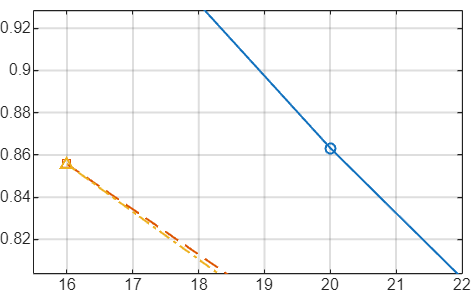


% print(fig1, 'F5-1.png', '-dpng', '-r1200');


%---------generate sub fig with fixed axis
% 1)

% -----------Desired sizes (cm)
figW_sub = 16.8/2;   % figure width
figH_sub = 16.8*0.618/2;    % figure height
axW  = 0.9*figW_sub;   % axes width
axH  = figH_sub*0.9;    % axes height
axLeft = (figW_sub-axW)./1.4;  % left margin (from figure left edge)
axBottom = (figH_sub-axH)./1.5; % bottom margin

x_limits = [15.5 22];
y_limits = ([ -8.75 -7]+20)./14;
fig11 = figure;
set(fig11, ...
    'Units','centimeters',  'Position',[2 2 figW_sub figH_sub], ...
    'PaperUnits','centimeters','PaperPosition',[0 0 figW_sub figH_sub], ...
    'PaperSize',[figW_sub figH_sub]);

% ------------ copy axis-----------
ax11 = copyobj(ax1, fig11);
set(ax11, 'Units','centimeters', ...
    'Position',[axLeft axBottom axW axH]);

% ------------set range------
xlim(ax11, x_limits);
ylim(ax11, y_limits);
xlabel('')   % deletes the X‑label
ylabel('')   % deletes the Y‑label
title('')    % deletes the title (if needed)

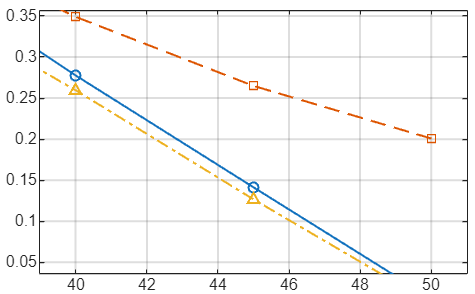

drawnow;  % draw zoom figure
% --------output figure--------
% print(fig11,'F2_zoom1.png','-dpng','-r1200');



%---------generate sub fig with fixed axis
% 2

% -----------Desired sizes (cm)-------------
figW_sub = 16.8/2;   % figure width
figH_sub = 16.8*0.618/2;    % figure height
axW  = 0.9*figW_sub;   % axes width
axH  = figH_sub*0.9;    % axes height
axLeft = (figW_sub-axW)./1.2;  % left margin (from figure left edge)
axBottom = (figH_sub-axH)./1.5; % bottom margin

x_limits = [39 51];
y_limits = ([ -19.5 -15]+20)./14;
fig12 = figure;
set(fig12, ...
    'Units','centimeters',  'Position',[2 2 figW_sub figH_sub], ...
    'PaperUnits','centimeters','PaperPosition',[0 0 figW_sub figH_sub], ...
    'PaperSize',[figW_sub figH_sub]);

% 2) 复制坐标区
ax12 = copyobj(ax1, fig12);
set(ax12, 'Units','centimeters', ...
    'Position',[axLeft axBottom axW axH]);

% 3) 设置放大范围
xlim(ax12, x_limits);
ylim(ax12, y_limits);
xlabel('')   % deletes the X‑label
ylabel('')   % deletes the Y‑label
title('')    % deletes the title (if needed)


% -----------output_figure-----------
% print(fig12,'F5_zoom2.png','-dpng','-r1200');


## data analysis, ploting the best S-D distance

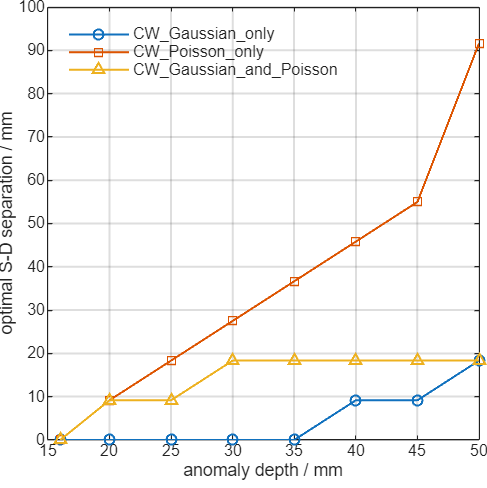

close all;

% --------------------Desired sizes (cm)
figW = 17.2/2;   % figure width
% figH = 17.2*0.618;    % figure height, too high here
figH = 17.2/2;    % figure height
axW  = figW-3.5*0.282;    % axes width
axH  = figH-3.5*0.282;    % axes height
axLeft = 3*0.282;  % left margin (from figure left edge)
axBottom = 3*0.282; % bottom margin

% -----------------Create the figure at the given size
fig2 = figure;
ax2 = axes('Parent',fig2);

set(fig2, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax2, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig

x = brain_radius - tumour_pos_range;

% Define one style spec per curve: [LineStyle, Marker]
% You can mix-and-match '-' '--' '-.' ':'  with markers 'o', 's', '^', etc.
lineSpecs = {'-','--','-.',':','-','-','-'};   % line styles
markers = {'o', 's', '^', 'v', 'd', 'p', 'x'};

labels = metrics;

hold on
for k = 1:numel(metrics)
    plot(ax2, x,opt_D.(metrics{k}), ...
        'LineStyle' , lineSpecs{k}(1), ...
        'LineWidth' , 1, ...
        'Marker'    , markers{k}, ...
        MarkerSize=5);
end
hold off
box(ax2,'on'); grid on;
xlabel('anomaly depth / mm');
ylabel('optimal S-D separation / mm')

ax = gca;                       % current axes
ax.LineWidth   = 1;             % axes box thickness
ax.FontName    = 'Arial';
ax.FontSize    = 8;            % journal‐style font size
ax.TickDir     = 'in';         % ticks outside
legend(labels, 'Location','northwest', 'Box','off', ...
    'FontSize',8, 'FontName','arial','Interpreter','none');

% print(fig2, 'F5-2.png', '-dpng', '-r1200');

## plot figures on left and right axis

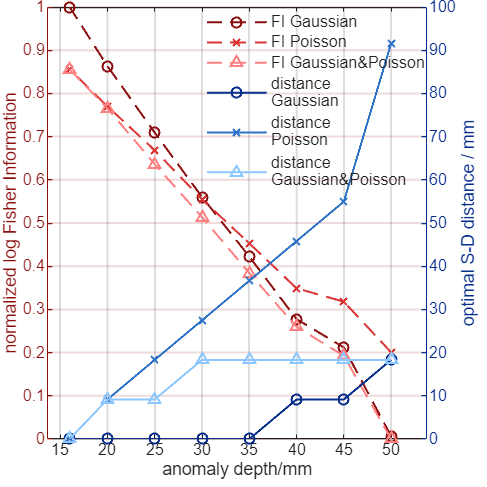

close all;

% -----------Desired sizes (cm)
figW = 17.2/2;   % figure width
% figH = 17.2*0.618;    % figure height, too high for this figure
figH = 17.2/2;    % figure height
axW  = figW-6.8*0.282;    % axes width
axH  = figH-3.5*0.282;    % axes height
axLeft = 3*0.282;  % left margin (from figure left edge)
axBottom = 3*0.282; % bottom margin

% -------- Create the figure at the given size
fig23 = figure;
ax23 = axes('Parent',fig23);

set(fig23, ...
    'Units',      'centimeters', ...
    'Position',   [2 2 figW figH], ...     % [left bottom width height]
    'PaperUnits', 'centimeters', ...
    'PaperPosition',[0 0 figW figH], ...
    'PaperSize',  [figW figH]);
set(ax23, ...
    'Units',      'centimeters', ...
    'Position',   [axLeft axBottom axW axH]);  % [left bottom width height] within fig


%-- Prepare data series and styles -----------------------------------------
x = brain_radius - tumour_pos_range;

h = gobjects(6,1); % Pre-allocate an object

lineSpecs_left = {'--','--','--'};   % line styles
lineSpecs_right = {'-','-','-'};   % line styles

markers = {'o', 'x', '^'};

% you can customize markers too, e.g. '-o','--s', etc.
% lineSpecs = {'-o','--s','-.^',':v','-d','-p','-x'};

labels = {'FI Gaussian','FI Poisson','FI Gaussian&Poisson',sprintf('distance\nGaussian'),sprintf('distance\nPoisson'),sprintf('distance\nGaussian&Poisson')};


% === 颜色设计 ===
deepRed  = [0.55, 0.06, 0.06];   % deep red for the left axis
reds = [  % three types of red
    0.55, 0.06, 0.06;
    0.85, 0.20, 0.20;
    1.00, 0.50, 0.50
    ];

deepBlue = [0.03, 0.18, 0.55];   % deep blue for the right axis
blues = [ % three types of blue
    0.03, 0.18, 0.55;
    0.18, 0.45, 0.78;
    0.55, 0.78, 1.00
    ];


nMetric = numel(metrics);
nX      = numel(x);
data    = zeros(nX, nMetric);

for k = 1:nMetric
    data(:,k) = log10(opt_FI.(metrics{k}));
end

%-- 2) Compute global min/max just once ------------------------
minVal = min(data,[],'all');
maxVal = max(data,[],'all');
range  = maxVal - minVal;

%-- 3) Normalize -------------------------------------------------
normData = (data - minVal) / range;
hold on
yyaxis left
for k = 1:nMetric
    h(k) = plot(ax23, x, normData(:,k), ...
        lineSpecs_left{k}, ...
        'Color',reds(k,:),...
        'LineWidth' , 1, ...
        'Marker'    , markers{k}, ...
        'MarkerSize', 5);
end
hold off
ax23.YColor = deepRed;   % left axis color

ylabel('normalized log Fisher Information');


hold on
yyaxis right
for k = 1:numel(metrics)
    h(k+3) = plot(ax23, x,opt_D.(metrics{k}), ...
        'Color',blues(k,:),...
        'LineStyle' , lineSpecs_right{k}(1), ...
        'LineWidth' , 1, ...
        'Marker'    , markers{k}, ...
        MarkerSize=5);
end
hold off
ax23.YColor = deepBlue;   % right axis color
box(ax23,'on'); grid on;
ylabel('optimal S-D distance / mm')


%-- Beautify ----------------------------------------------------------------
xlim(ax23,[13.7 53.7])
% ylim(ax1,[-6.66 -2.02])
xlabel('anomaly depth/mm');
grid on; box(ax23,'on');
ax = gca;
ax.LineWidth = 1;
ax.FontSize = 8;
ax.FontName = 'Arial';

legend(h,labels, "Position", [0.41365,0.59887,0.47385,0.38], 'Box','off', ...
    'FontSize',8, 'FontName','arial','Interpreter','none');

print(fig23, 'F1_5_240905.png', '-dpng', '-r1200');


%

clear
data1 = load("tpsfs_jacobians_dense_AngRang_pi_3_tumpos25_old.mat");
data2 = load('tpsfs_jacobians_dense_AngRang_pi_3_tumpos25_more_old.mat');
sum(data1.tpsfs,1)./sum(data2.tpsfs,1)

ans =     2.0368    2.0036    1.9953    2.0173    1.9731    2.0340    2.1604    1.8173    1.8071    1.6860    1.8227    2.3131    2.3579    1.7292    2.0491    2.4969    1.7808    1.9886    2.0338    2.0043    2.0073    2.0081    2.0094    2.1044    2.2181    1.9697    2.2023    2.2445    2.3629    2.0375    1.5440    4.5364    2.2789    3.0685    2.0164    2.0055    2.0213    2.0125    2.0151    2.0130    1.9322    1.9894    2.0939    2.1914    2.2413    1.7973    2.1234    2.2053    2.5386    1.9140


sum(data1.jacobians,[1 2 3])./sum(data2.jacobians,[1 2 3])

ans = ans(:,:,1,1) =

    3.9606


ans(:,:,1,2) =

    3.9952


ans(:,:,1,3) =

    4.0144


ans(:,:,1,4) =

    4.0030


ans(:,:,1,5) =

    4.0859


ans(:,:,1,6) =

    4.2416


ans(:,:,1,7) =

    4.0903


ans(:,:,1,8) =

    3.8344


ans(:,:,1,9) =

    4.0351


ans(:,:,1,10) =

    3.4928


ans(:,:,1,11) =

    3.2049


ans(:,:,1,12) =

    4.3639


ans(:,:,1,13) =

    4.8769


ans(:,:,1,14) =

    3.1348


ans(:,:,1,15) =

    3.3318


ans(:,:,1,16) =

    3.9456


ans(:,:,1,17) =

    4.2780


ans(:,:,1,18) =

    3.9785


ans(:,:,1,19) =

    3.9453


ans(:,:,1,20) =

    4.0119


ans(:,:,1,21) =

    3.9702


ans(:,:,1,22) =

    4.0098


ans(:,:,1,23) =

    4.0106


ans(:,:,1,24) =

    4.2027


ans(:,:,1,25) =

    4.1570


ans(:,:,1,26) =

    3.7387


ans(:,:,1,27) =

    4.2024


ans(:,:,1,28) =

    4.1789


ans(:,:,1,29) =

    4.5245


ans(:,:,1,30) =

    4.2724


ans(:,:,1,31) =

    4.4420


ans(:,:,1,32) =

    7.3824


ans(:,:,1,33) =

    4.8365


ans(:,:,1,34)


load("tpsfs_jacobians_dense_AngRang_pi_3_tumpos25_old.mat")
jacobians = jacobians./4;
tpsfs = tpsfs./2;

save("tpsfs_jacobians_dense_AngRang_pi_3_tumpos25.mat","tpsfs","jacobians")